# PROYECTO PRIME

Teresa González García y María José Medina Hernández

format compact; clear all; close all;

## 1. Elección de los parámetros de simulación

### Parámetros generales

Fs=250*10^3; % Frecuencia de muestreo
Ts=1/Fs; % Periodo de muestreo

### Parámetros de modulación PSK

m_ary=[2 4 8]; % Número de símbolos de la constelación PSK
m_dpsk=log2(m_ary);

### Parámetros de modulación OFDM

Nc= 96; % Número de portadoras
NFFT=512; % Tamaño FFT
Ncp=48; % Tamaño prefijo ciclico
Tsimb=2.24*10^-3; % NFFT*Ts + Ncp*Ts. Duracion total simbolo OFDM
delta_f=Fs/NFFT; % Separacion entre f portadoras

### Parámetros de corrección de errores

R=1/2; %Convolutional coding rate

### Parámetros de aleatorización y desfase

% Secuencia PRBS
scrambler = [0,0,0,0,1,1,1,0,1,1,1,1,0,0,1,0,1,1,0,0,1,0,0,1,0,0,0,0,0,0,1,0,0,0,1,0,0,1,1,0,0,0,1,0,1,1,1,0,1,0,1,1,0,1,1,0,0,0,0,0,1,1,0,0,1,1,0,1,0,1,0,0,1,1,1,0,0,1,1,1,1,0,1,1,0,1,0,0,0,0,1,0,1,0,1,0,1,1,1,1,1,0,1,0,0,1,0,1,0,0,0,1,1,0,1,1,1,0,0,0,1,1,1,1,1,1,1];

### Parámetros de simulación

Para calcular el número de símbolos OFDM por trama, tenemos en cuenta que, como máximo, esta puede durar 100ms ya que es el tiempo máximo en el que se puede considerar el canal estable cuando sea dispersivo. Obtenemos Nofdm = 44.

Tmax=100*10^-3; % Duración máxima de una trama
Nofdm= floor(Tmax/(Tsimb)); % Nofdm

Puesto que se quieren obtener valores de BER fiables inferiores incluso a 10^-4, se necesitan transmitir al menos 10^-4 bits si se quiere obtener esta sensibilidad. Para sensillez del código, se utilizará un número de bits proporcional al número de portadoras, a log2(m-ary) y al número de símbolos OFDM por trama. El mínimo común múltiplo de estos cuatro parámetros es mayor a 10^-4, por lo que es un tamaño válido. En total obtenemos 25344.

Nbits = Nc*lcm(2,3)*Nofdm;

Para calcular el número total de tramas, se divide el número total de bits entre los bits por trama. En total obtenemos 6 para DBPSK, 3 para DQPSK y 2 para DBPSK.

Nbits_trama_DPSK= Nofdm*Nc*m_dpsk;
N_tramas_DPSK=Nbits./Nbits_trama_DPSK;


## 2. Transmisión en un canal ideal

### Transmisión sin aleatorización 

% TODO: poner un flag para que aleatorice o no para demostrar que funciona sin y con aleatorización

% Generación de una secuencia de bits aleatoria
txbits = randi(2,1,Nbits)-1;

% Transmisión con modulación en OFDM sobre DBPSK, DQPSK y D8PSK
x_tx_DBPSK= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT);
x_tx_DQPSK= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT);
x_tx_D8PSK= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT);

% Recepción con modulación en OFDM sobre DBPSK, DQPSK y D8PSK
rxbits_DBPSK=receptor(x_tx_DBPSK, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
rxbits_DQPSK=receptor(x_tx_DQPSK, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
rxbits_D8PSK=receptor(x_tx_D8PSK, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);

#### Cálculo del error de transmisión

Cálculo del error de transmisión mediante la comparación de los bits transmitidos con los recibidos

error_dbpsk = sum(abs(txbits-rxbits_DBPSK))

error_dbpsk = 0

error_dqpsk = sum(abs(txbits-rxbits_DQPSK))

error_dqpsk = 0

error_d8psk = sum(abs(txbits-rxbits_D8PSK))

error_d8psk = 0

### 3. Transmisión en presencia de ruido AWGN

Comparativa BERs teóricas frente a simuladas

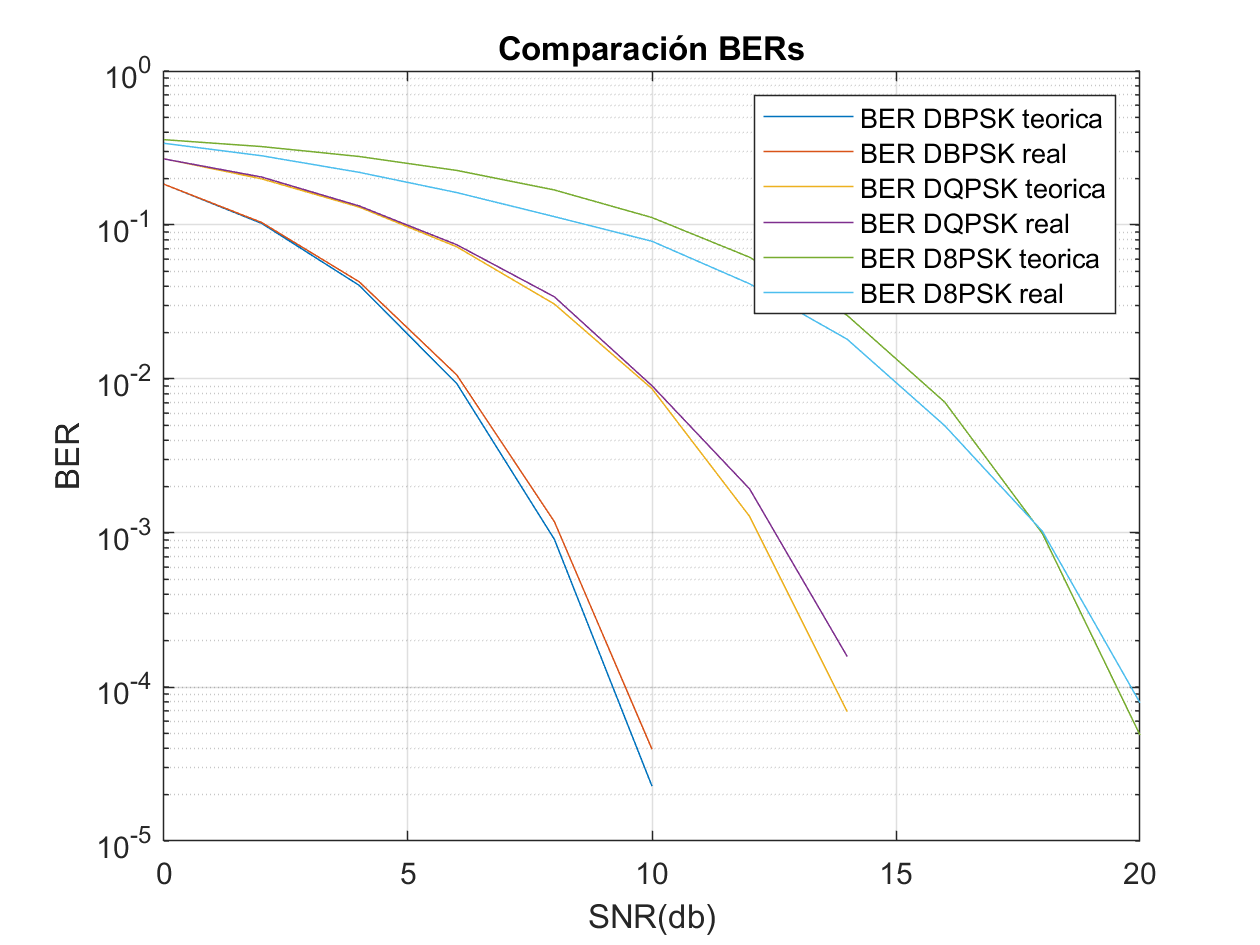

% vector SNR
SNR_db = 0:2:35;

% Cálculo del factor de ancho de banda para distribuir SNR tan solo en la parte
% del espectro con portadoras (Nc)
fb = 10*log10( (NFFT/2)/Nc);

%BER's teoricas de cada modulacion
BER_teor_DBPSK= DBPSK_BER(SNR_db);
BER_teor_DBPSK(find(BER_teor_DBPSK<1e-6))=NaN;
BER_teor_DQPSK= DQPSK_BER(SNR_db);
BER_teor_DQPSK(find(BER_teor_DQPSK<1e-6))=NaN;
BER_teor_D8PSK= D8PSK_BER(SNR_db);
BER_teor_D8PSK(find(BER_teor_D8PSK<1e-6))=NaN;

% Bucle calculo BER_real_DBPSK
for k=1:length(SNR_db)
    %y_noise=zeros(1, length(x_tx_DBPSK));
    y_noise_dbpsk=awgn(x_tx_DBPSK,SNR_db(k)-fb,'measured');
    y_noise_dqpsk=awgn(x_tx_DQPSK,SNR_db(k)-fb,'measured');
    y_noise_d8psk=awgn(x_tx_D8PSK,SNR_db(k)-fb,'measured');
    
    y_rx_noise_dbpsk=receptor(y_noise_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_dqpsk=receptor(y_noise_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_d8psk=receptor(y_noise_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
    
    
    diferencia_dbpsk=abs(txbits-y_rx_noise_dbpsk);
    diferencia_dqpsk=abs(txbits-y_rx_noise_dqpsk);
    diferencia_d8psk=abs(txbits-y_rx_noise_d8psk);
    
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

% Representacion BER vs SNR para todos los tipos de modulacion
figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

D8PSK + BER CONSTELACION PUNTOS MAS JUNTOS.

        2.   Inclusión de modelo de canal e inclusión de ecualizador

%canal variante en f. Corresponde a un filtro digital de k=9 posiciones en total (en el dominio del tiempo
% discreto):
h=[-0.1,0.3,-0.5,0.7,-0.9,0.7, -0.5, 0.3, -0.1]; % h=[a0...a8]; atenuaciones

   h[n] produce atenuación y retardo por reflexiones dentro de un canal multipath (retardo máximo 8) en la señal a transmitir.

s(t) -> TX

y(t)-> RX

y(t)=conv(s(t),h(t)) -> dominio discreto -> y[n]= conv(s[n],h[n]). 

y[n]=sum(att*s[n-k])- Seguir con esto en latex

H(f) en dbW

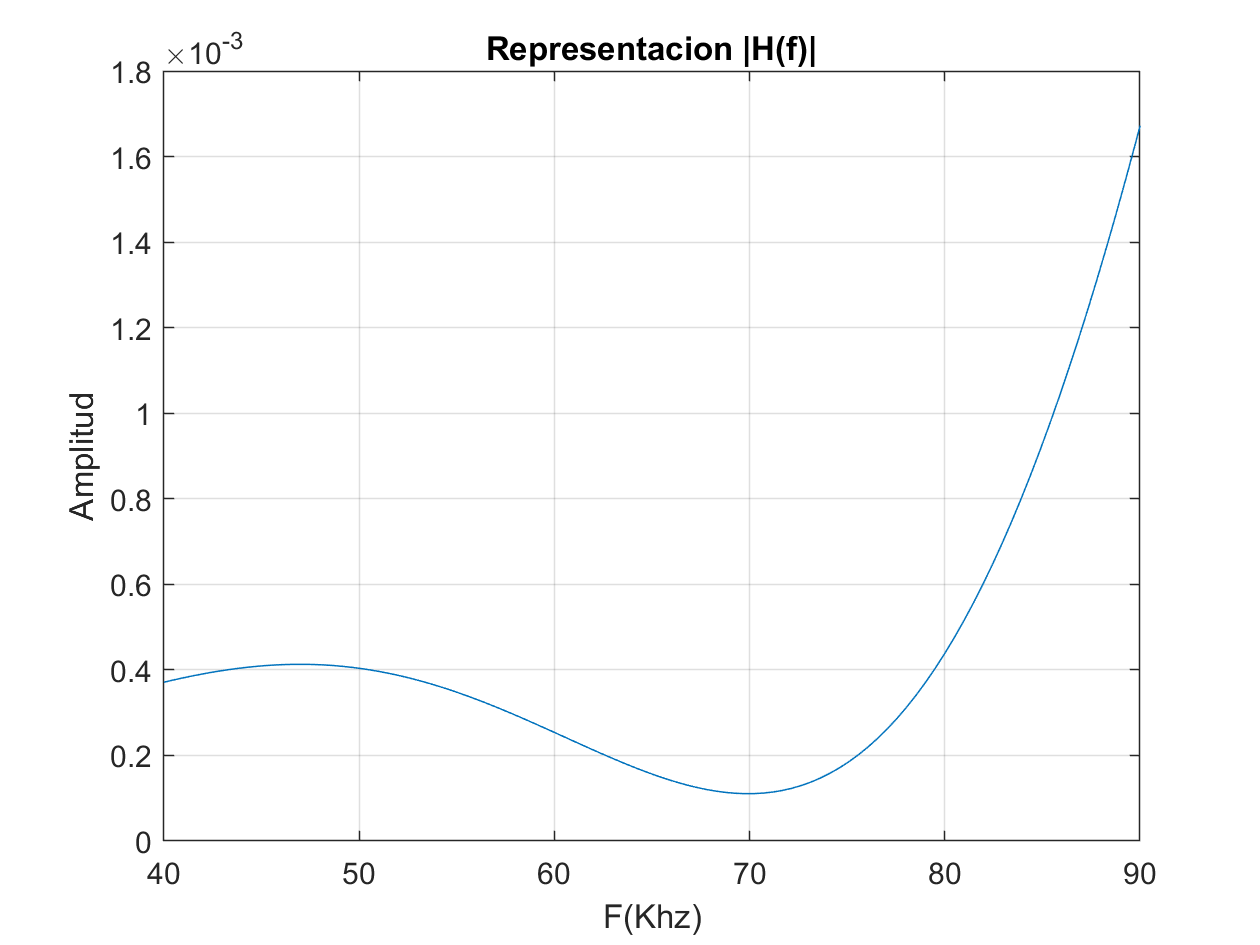

% vector f (paso Fs) -> mitad puntos NFFT espectro + y mitad -. Preguntar

% H(f) es la respuesta al impulso del canal -> FFT.
H=fft(h,NFFT)/NFFT;
f=linspace(-Fs/2,Fs/2, length(H));

%Representacion |H(f)| en el dominio de la frecuencia (unidades naturales)
figure
plot(f/1000,abs(fftshift(H)));
title('Representacion |H(f)|');
xlabel('F(Khz)');
xlim([40,90]);
ylabel('Amplitud');
grid on

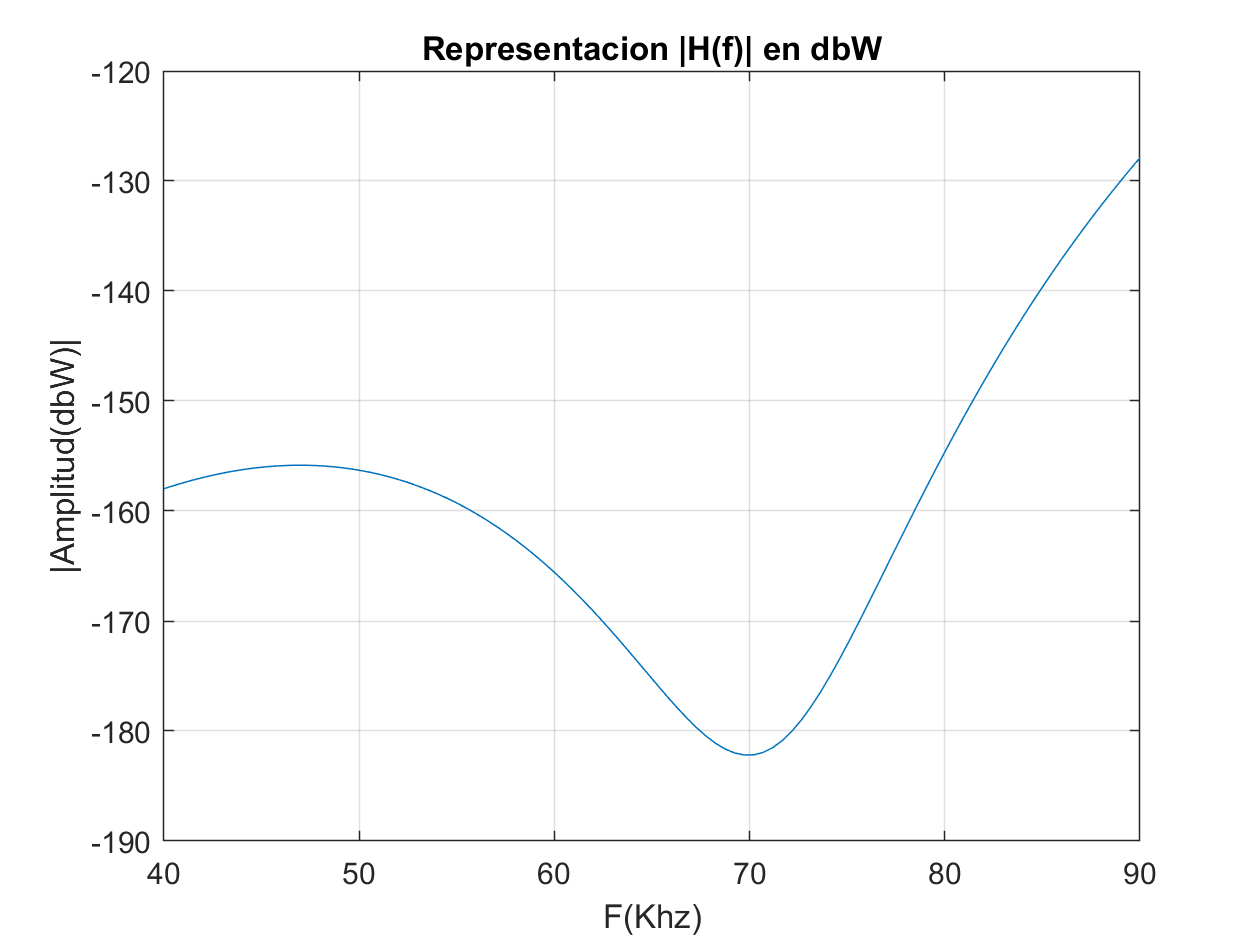

% Representacion |H(f)| el dominio de la frecuencia (db)
figure
plot (f/1000,20*log(abs(fftshift(H))))
title('Representacion |H(f)| en dbW');
xlabel('F(Khz)');
ylabel('|Amplitud(dbW)|');
grid on
xlim([40,90]);

## Con canal

Variables globales

global pilotos_dbpsk
global pilotos_dqpsk
global pilotos_d8psk

%convolucion lineal sin cp y añadimos awgn
y_canal_DBPSK=conv(x_tx_DBPSK,h);
y_canal_DBPSK =y_canal_DBPSK(1:end-length(h)+1)

y_canal_DBPSK =    -0.6000    0.8632    0.5055   -0.1889   -3.2769    2.1484   -1.2877    5.6698   -3.5426   -3.8696    2.3082    2.4818    0.9123   -3.3469   -2.5932    5.0441    1.1307   -3.8502    0.6506   -0.6981    0.7786    4.2296   -4.4212   -2.5670    5.2800   -2.8282   -0.6328    6.1057   -5.7149   -3.7753    6.9989   -1.2016   -1.1715    2.9911   -6.3295    0.1394    8.2306   -3.7973   -3.2339    2.7992   -2.8194    2.4651    3.6752   -6.2272    0.4236    4.0302   -3.4899    1.8675    1.1990   -4.8998


y_canal_DQPSK=conv(x_tx_DQPSK,h);
y_canal_DQPSK =y_canal_DQPSK(1:end-length(h)+1)

y_canal_DQPSK =     0.6000   -2.2779    3.7527   -3.1368    0.7714    2.7318   -4.9971    3.9277   -0.1108   -3.8413    3.9811    0.8388   -4.4597    2.0474    1.6037   -1.7746    1.1587   -0.9680   -1.2861    3.0840   -0.2584   -2.9589    0.9390    1.7157    0.0649   -0.8536   -1.4803    0.2016    2.0660    1.1272   -1.7820   -2.8332    0.9814    3.5713    0.2329   -2.5948   -1.4313    0.4021    1.7143    1.9153   -0.8847   -3.0334   -0.0240    1.5196    0.2428    2.7630   -0.5038   -6.9598    1.4592    6.7761



y_canal_D8PSK=conv(x_tx_D8PSK,h);
y_canal_D8PSK =y_canal_D8PSK(1:end-length(h)+1)

y_canal_D8PSK =    -0.7071    2.4436   -4.2323    4.9684   -4.9431    2.5768    1.0059   -3.8901    2.8750   -0.7103   -0.1519    2.8690   -3.9549   -0.6529    2.8820   -1.2903    2.7559   -1.0293   -5.9988    4.2984    3.2906   -2.5190    0.9697   -3.8447   -1.1875    7.6427   -1.5529   -4.3349    1.7418   -2.1317    1.9309    4.7866   -4.3249   -2.5064    1.1793    0.2480    4.5508   -1.2577   -6.3085    2.7208    2.3971   -0.5364    2.1948   -4.2385   -2.5003    6.4946   -0.6329   -3.8303    2.7962   -0.5414


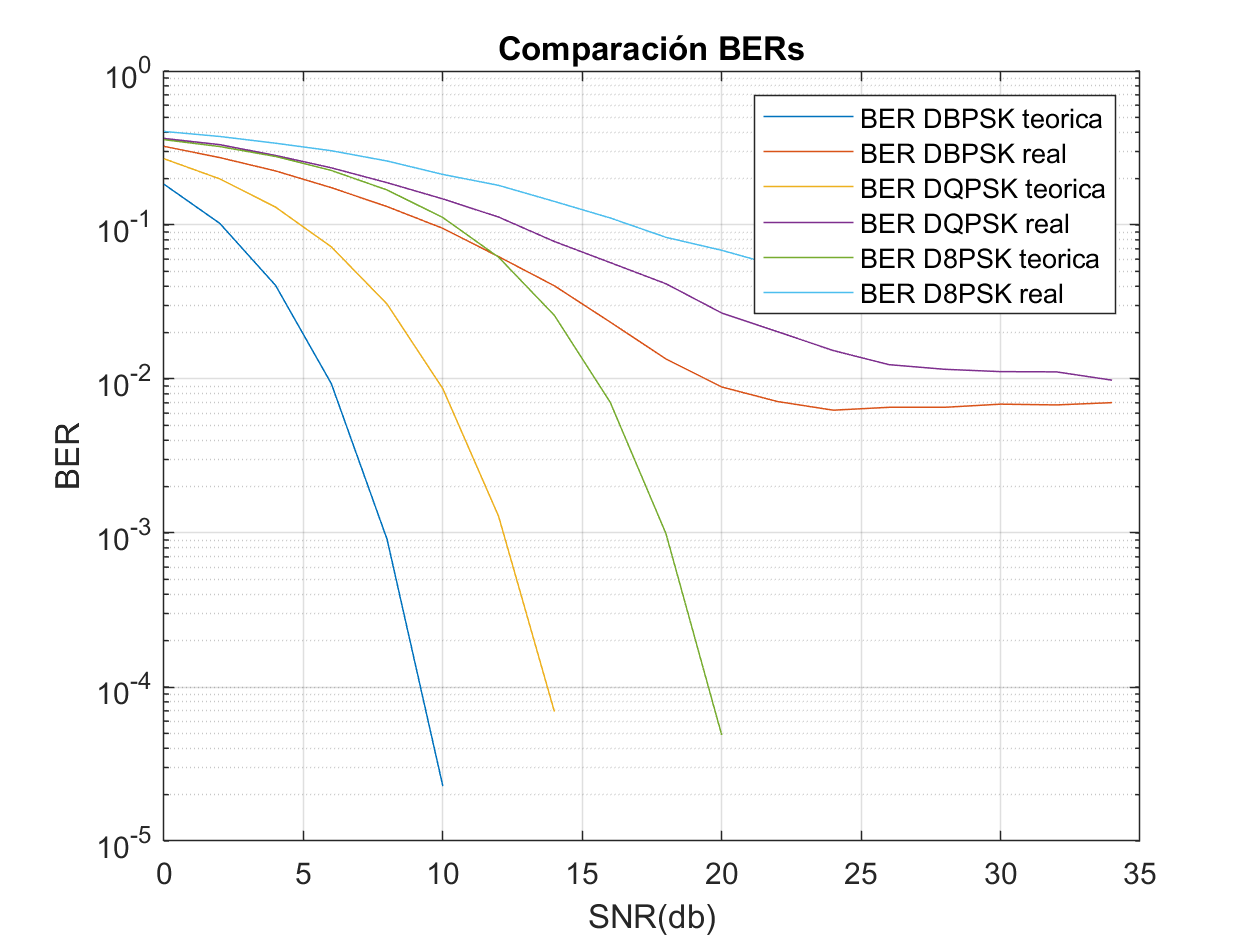

%añadimos el ruido
for k=1:length(SNR_db)
    %y_noise=zeros(1, length(x_tx_DBPSK));
    y_noise_canal_dbpsk=awgn(y_canal_DBPSK,SNR_db(k)-fb,'measured');
    y_noise_canal_dqpsk=awgn(y_canal_DQPSK,SNR_db(k)-fb,'measured');
    y_noise_canal_d8psk=awgn(y_canal_D8PSK,SNR_db(k)-fb,'measured');
    
    y_rx_noise_canal_dbpsk=receptor(y_noise_canal_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_canal_dqpsk=receptor(y_noise_canal_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_canal_d8psk=receptor(y_noise_canal_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
    
    
    diferencia_dbpsk=abs(txbits-y_rx_noise_canal_dbpsk);
    diferencia_dqpsk=abs(txbits-y_rx_noise_canal_dqpsk);
    diferencia_d8psk=abs(txbits-y_rx_noise_canal_d8psk);
    
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

FONDO DE BER EN TORNO 10^-2. eq lo quitara. BPSK MENOR BER

%incluir prefijo ciclico ncp=48. asi se puede recuperar el canal con la
%inversa (problema FFT)
%vectores extendidos
x_tx_DBPSK_cp= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT, Ncp);
x_tx_DQPSK_cp= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT, Ncp);
x_tx_D8PSK_cp= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT, Ncp);

Suponemos que desconocemos el canal.  Finjimos que conocemos el primer simbolo OFDM que recibes entre el primero que has enviado para estimar el canal

%receptor sin ruido para ver que nos quita bien el prefijo

y_rx_DBPSK_cp=receptor(x_tx_DBPSK_cp, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT, Ncp);
y_rx_DQPSK_cp=receptor(x_tx_DQPSK_cp, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT, Ncp);
y_rx_D8PSK_cp=receptor(x_tx_D8PSK_cp, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT, Ncp);


Comprobacion tras ecualizacion y sin ruido error=0.

error_dbpsk = sum(abs(txbits-y_rx_DBPSK_cp))

error_dbpsk = 0

error_dqpsk = sum(abs(txbits-y_rx_DQPSK_cp))

error_dqpsk = 0

error_d8psk = sum(abs(txbits-y_rx_D8PSK_cp))

error_d8psk = 0

Convolucionamos con la extendida

y_canal_DBPSK_cp=conv(x_tx_DBPSK_cp,h);
y_canal_DBPSK_cp =y_canal_DBPSK_cp(1:end-length(h)+1);

y_canal_DQPSK_cp=conv(x_tx_DQPSK_cp,h);
y_canal_DQPSK_cp =y_canal_DQPSK_cp(1:end-length(h)+1);

y_canal_D8PSK_cp=conv(x_tx_D8PSK_cp,h);
y_canal_D8PSK_cp =y_canal_D8PSK_cp(1:end-length(h)+1);

Añadimos ruido para calcular BER

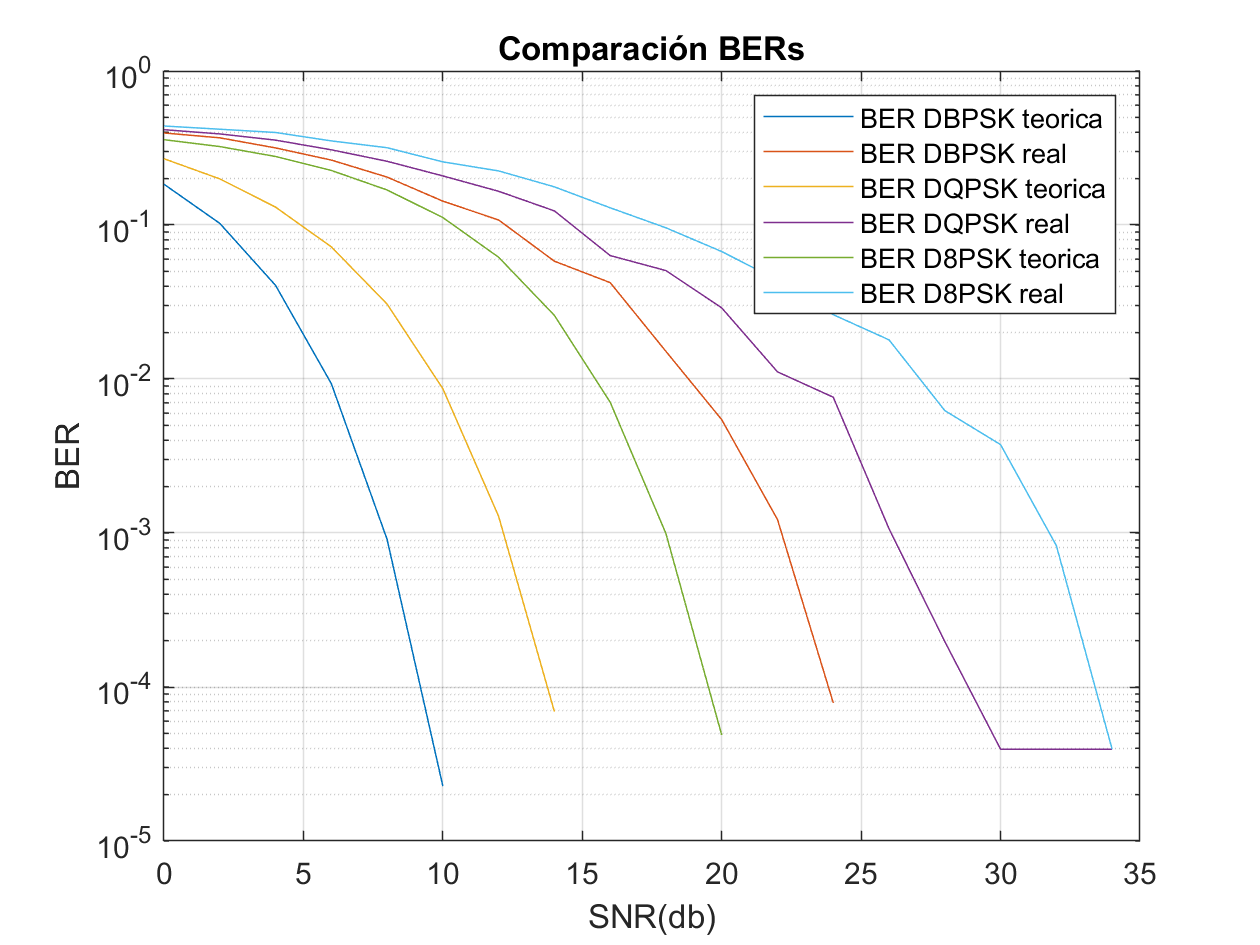

%añadimos el ruido

for k=1:length(SNR_db)
  
    y_noise_canal_dbpsk=awgn(y_canal_DBPSK_cp,SNR_db(k)-fb,'measured');
    y_noise_canal_dqpsk=awgn(y_canal_DQPSK_cp,SNR_db(k)-fb,'measured');
    y_noise_canal_d8psk=awgn(y_canal_D8PSK_cp,SNR_db(k)-fb,'measured');
    
    y_rx_noise_canal_dbpsk_cp=receptor(y_noise_canal_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT, Ncp);
    y_rx_noise_canal_dqpsk_cp=receptor(y_noise_canal_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT, Ncp);
    y_rx_noise_canal_d8psk_cp=receptor(y_noise_canal_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT, Ncp);
    
    
    diferencia_dbpsk=abs(txbits-y_rx_noise_canal_dbpsk_cp);
    diferencia_dqpsk=abs(txbits-y_rx_noise_canal_dqpsk_cp);
    diferencia_d8psk=abs(txbits-y_rx_noise_canal_d8psk_cp);
    
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

## FEC

- Parametros

# TODO

%añadimos nuevos bits por la redundancia del FEC (x2) y 8 bits de flush para poner a 0 los registros del codigo convolucional.
%Nbits info trama nuevos = (Nbitstrama_inicial-8)/2.
%como el numero de bits de info es la mitad, el numeros de tramas sera el
%doble.
%El numero de bits por trama es fijo por el standar (payload)

Ntramas = [12, 6, 4];
Nflush=8;

%3 Nbits en funcion de Ntrama.
% Nbits_1 = Ntramas(1)*(Nbits_trama_DPSK(1)-Nflush)*R;
% Nbits_2 = Ntramas(2)*(Nbits_trama_DPSK(2)-Nflush)*R; 
% Nbits_3 = Ntramas(3)*(Nbits_trama_DPSK(3)-Nflush)*R; 
 Nbits_1 = Ntramas(1)*((Nbits_trama_DPSK(1)*R)-Nflush);
 Nbits_2 = Ntramas(2)*((Nbits_trama_DPSK(2)*R)-Nflush);
 Nbits_3 = Ntramas(3)*((Nbits_trama_DPSK(3)*R)-Nflush);
txbits_1 = randi(2,1,Nbits_1)-1;
txbits_2 = randi(2,1,Nbits_2)-1;
txbits_3 = randi(2,1,Nbits_3)-1;


    2. Interleaving

%con prefijo
x_tx_DBPSK_cp_ileav= transmisor(txbits_1', m_ary(1), Nbits_trama_DPSK(1), Ntramas(1), Nc,scrambler, Nofdm, NFFT, Ncp, R);
x_tx_DQPSK_cp_ileav= transmisor(txbits_2', m_ary(2), Nbits_trama_DPSK(2), Ntramas(2), Nc,scrambler, Nofdm, NFFT, Ncp, R);
x_tx_D8PSK_cp_ileav= transmisor(txbits_3', m_ary(3), Nbits_trama_DPSK(3), Ntramas(3), Nc,scrambler, Nofdm, NFFT, Ncp, R);


y_rx_DBPSK_cp_ileav=receptor(x_tx_DBPSK_cp_ileav, m_ary(1), Nbits_trama_DPSK(1), Ntramas(1), Nc, scrambler, Nofdm, NFFT, Ncp, R);
y_rx_DQPSK_cp_ileav=receptor(x_tx_DQPSK_cp_ileav, m_ary(2), Nbits_trama_DPSK(2), Ntramas(2), Nc, scrambler, Nofdm, NFFT, Ncp, R);
y_rx_D8PSK_cp_ileav=receptor(x_tx_D8PSK_cp_ileav, m_ary(3), Nbits_trama_DPSK(3), Ntramas(3), Nc, scrambler, Nofdm, NFFT, Ncp, R);


Comprobar error tras interleaving

error_dbpsk = find(txbits_1-y_rx_DBPSK_cp_ileav)

error_dbpsk =
  1×0 empty double row vector


error_dqpsk = find(txbits_2-y_rx_DQPSK_cp_ileav)

error_dqpsk =
  1×0 empty double row vector


error_d8psk = find(txbits_3-y_rx_D8PSK_cp_ileav)

error_d8psk =
  1×0 empty double row vector
